# How to draw a bifurcation diagram

This code draws the bifurcation diagram from Figure 3.3 of

Goodman, R. H. [NLS bifurcations on the bowtie combinatorial graph and the dumbbell metric graph.](http://doi.org/10.3934/dcds.2019093) **Discrete & Continuous Dynamical Systems - A,** 39(4), 2203–2232 (2019). 

plus one extra branch to show how the code works.

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

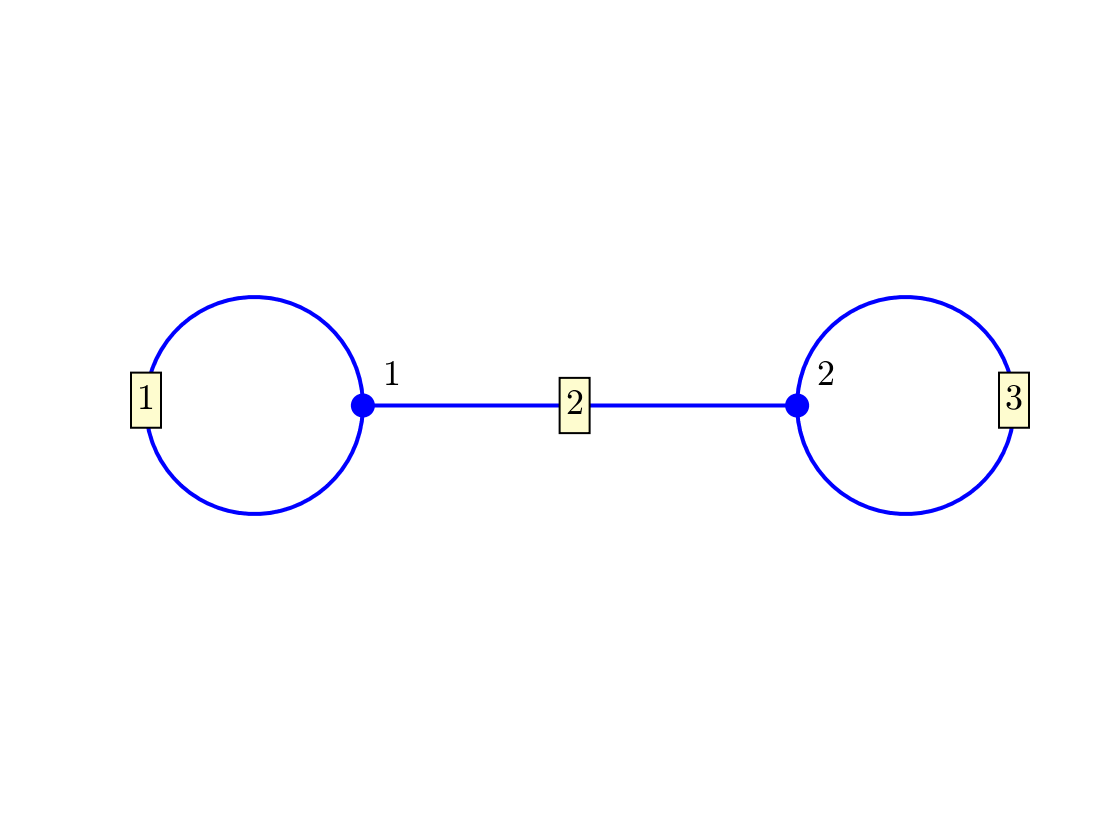

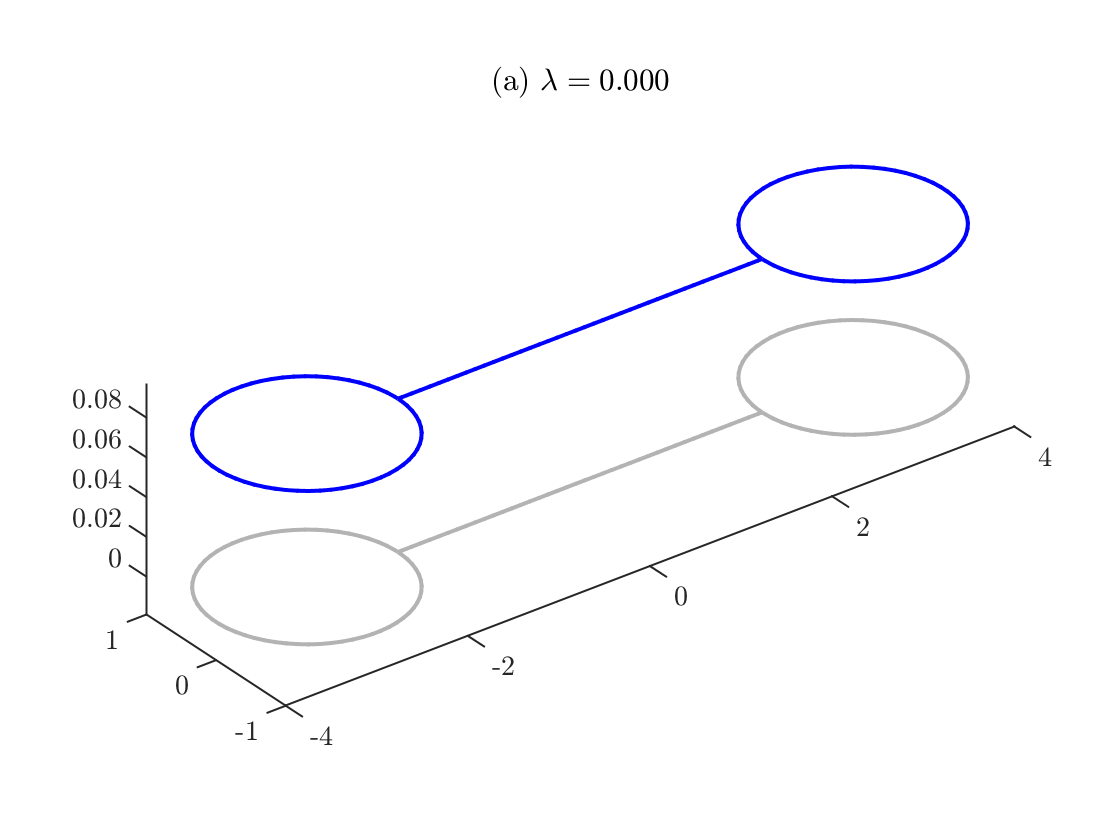

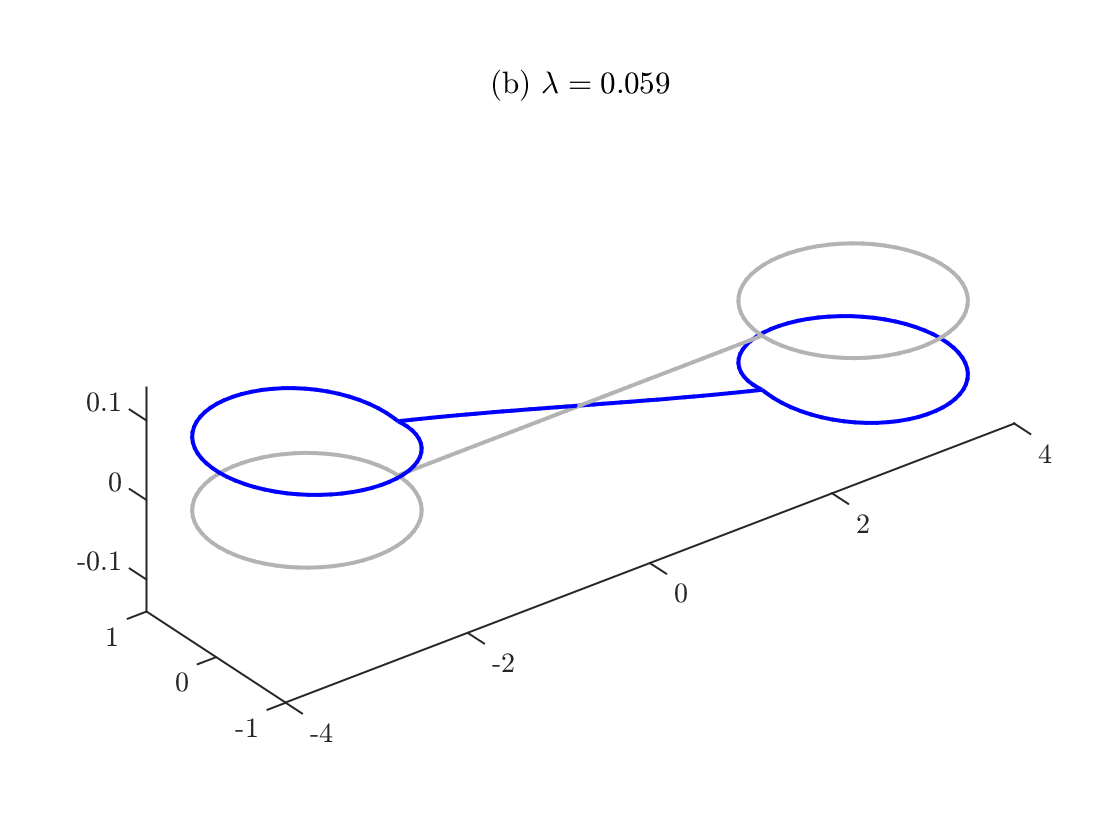

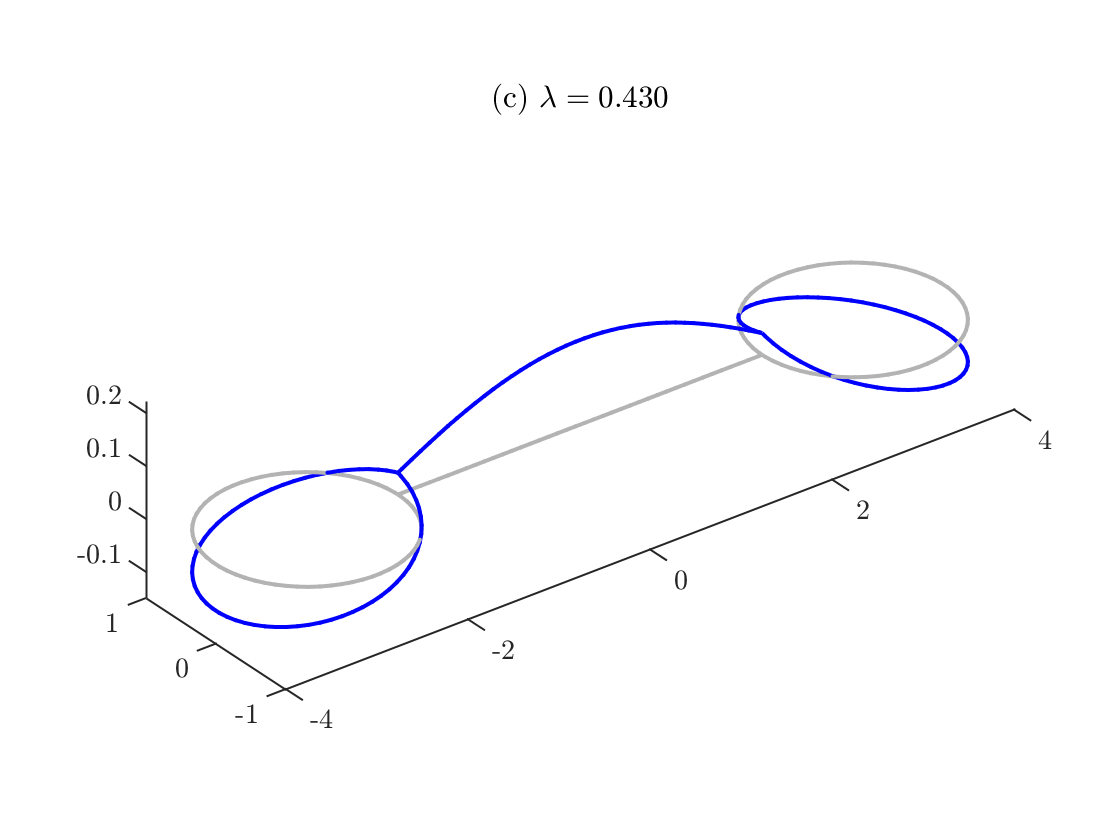

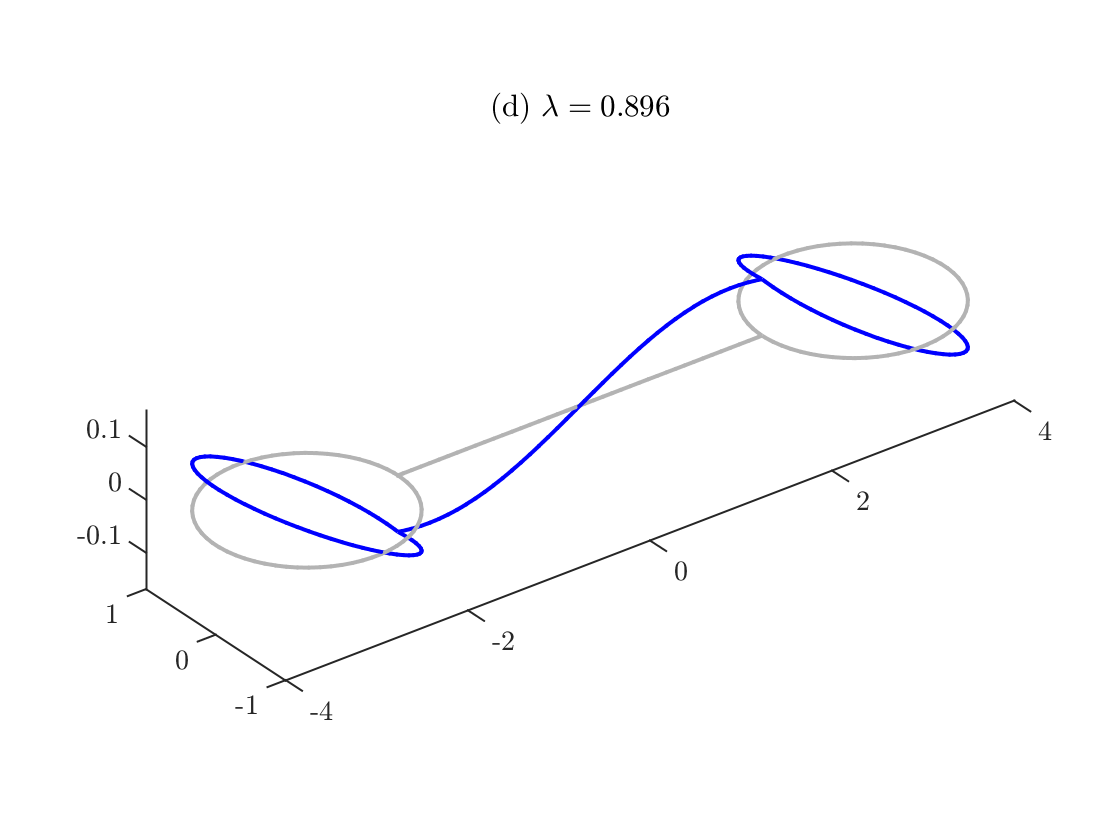

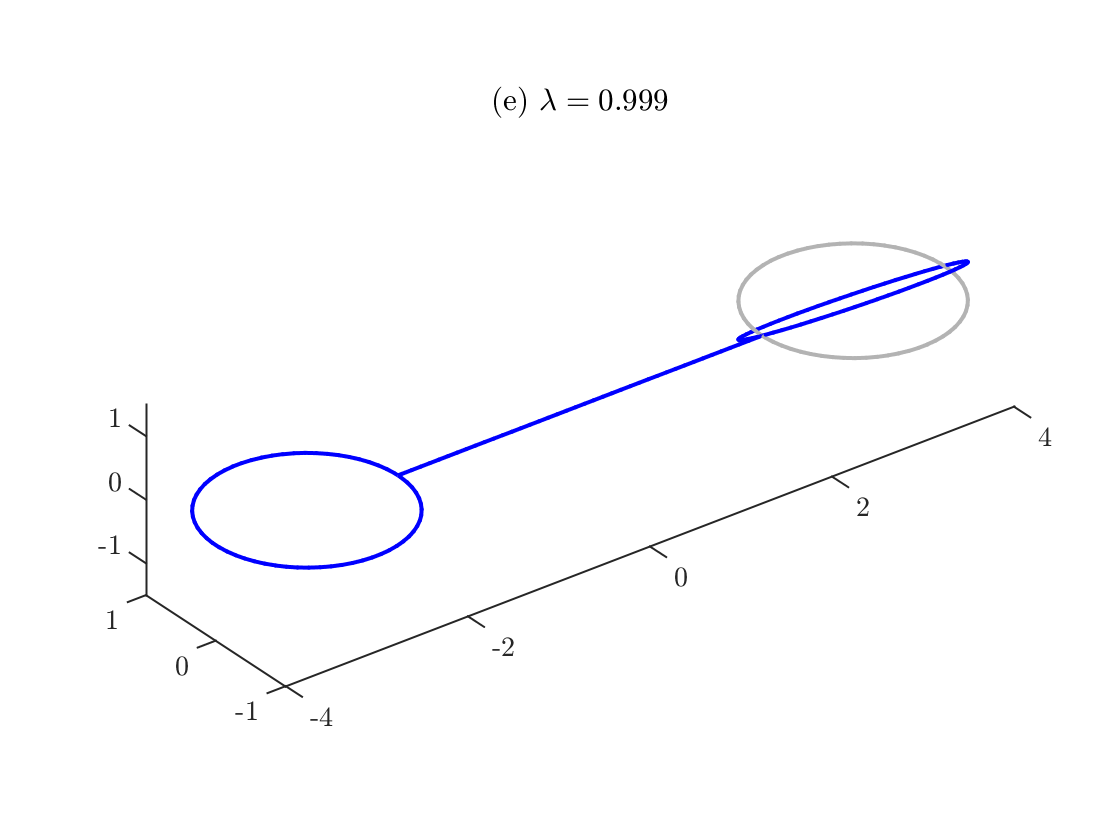

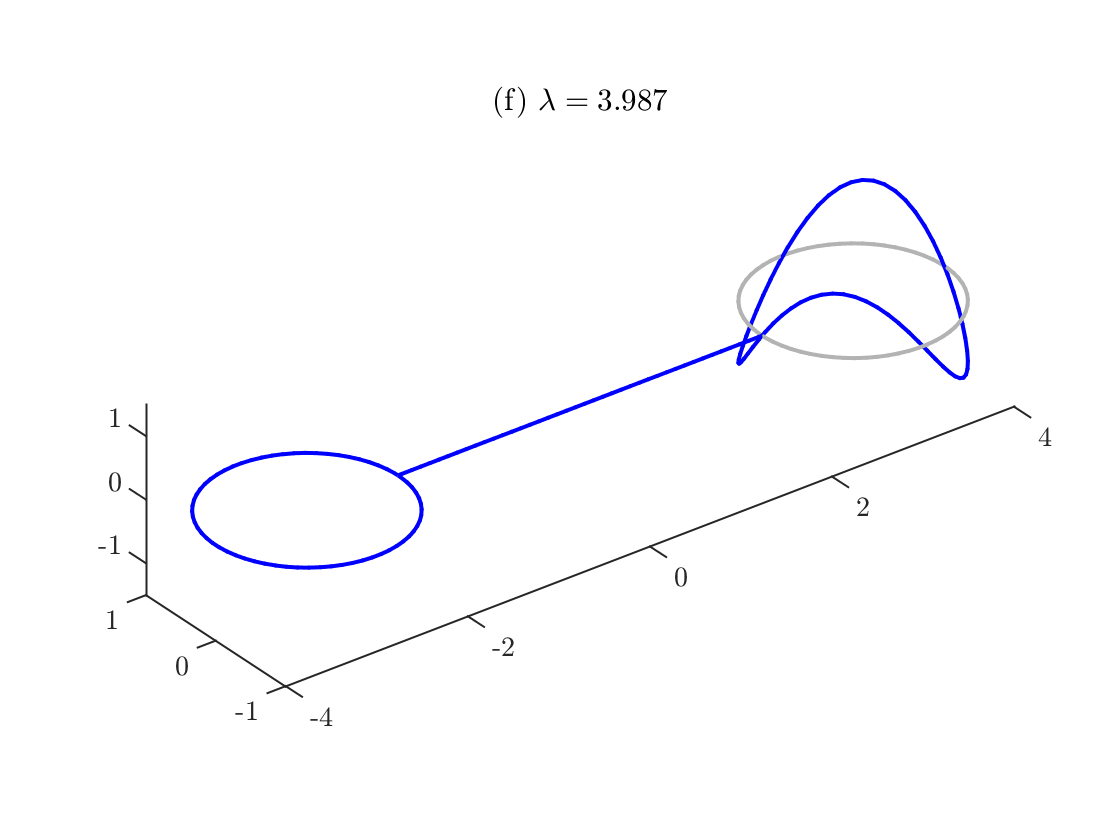

Saved to directory data/dumbbell/025.
Run number is 25.


runNumber=dumbbellEigenfunctionsSaveData(2*pi,4,64,40,4);

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig('dumbbell',runNumber,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/dumbbell/025/branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn2,bl2]=continueFromBranchPoint('dumbbell',runNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/dumbbell/025/branch002.
No branching bifurcations found.


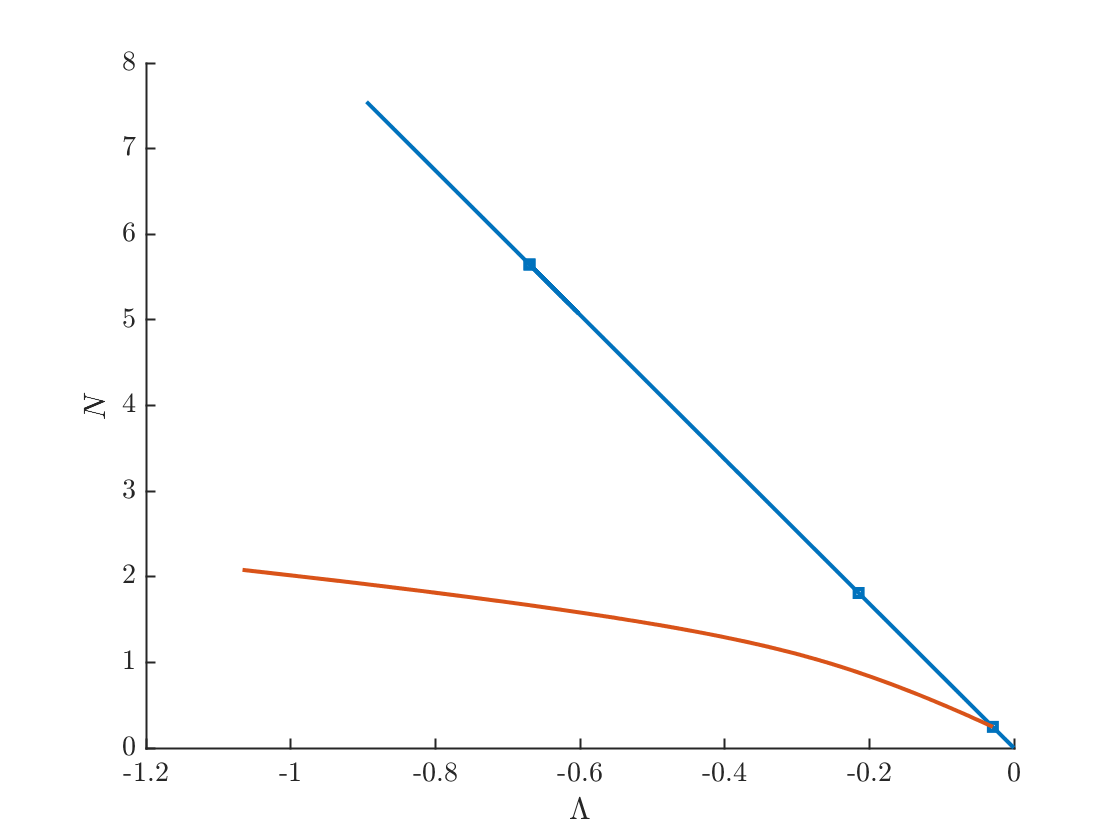

bifurcationDiagram('dumbbell',runNumber)

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn3,bl3]=continueFromBranchPoint('dumbbell',runNumber,bn1,bl1(2),1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/dumbbell/025/branch003.
Branching Bifurcation at solution number 12.


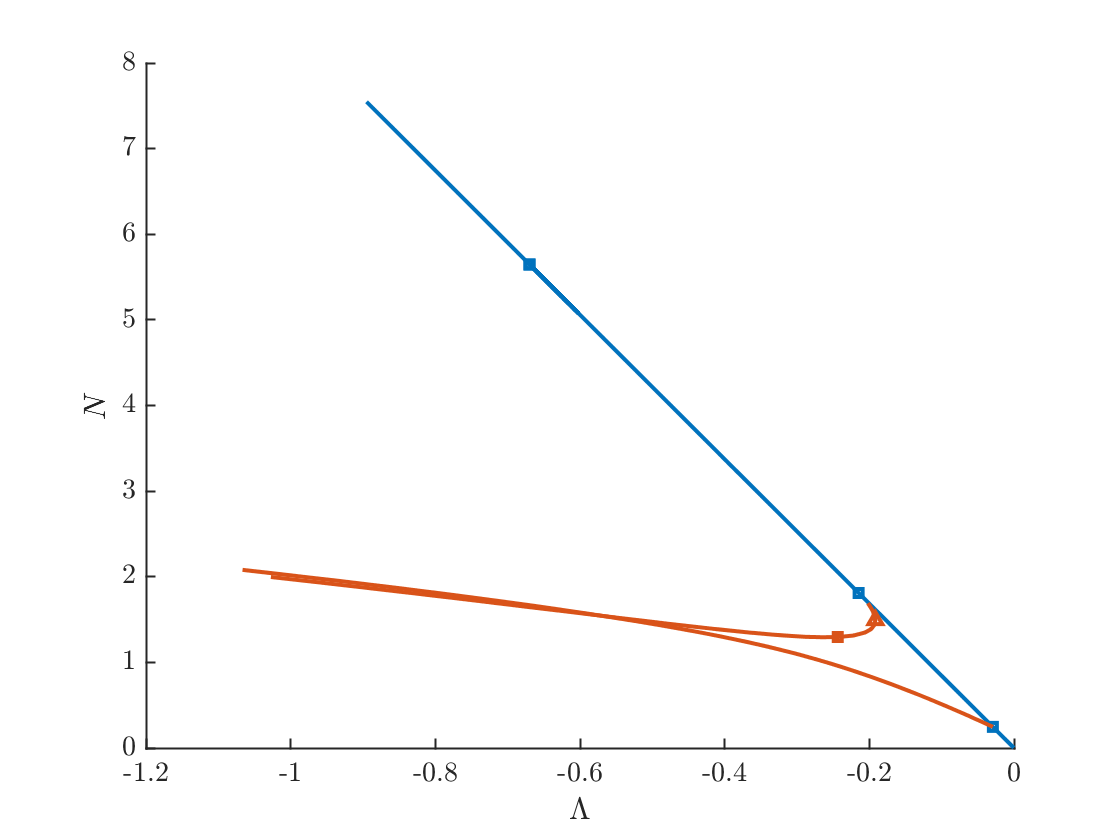

bifurcationDiagram('dumbbell',runNumber)

[bn4,bl4]=continueFromBranchPoint('dumbbell',runNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/dumbbell/025/branch004.
No branching bifurcations found.


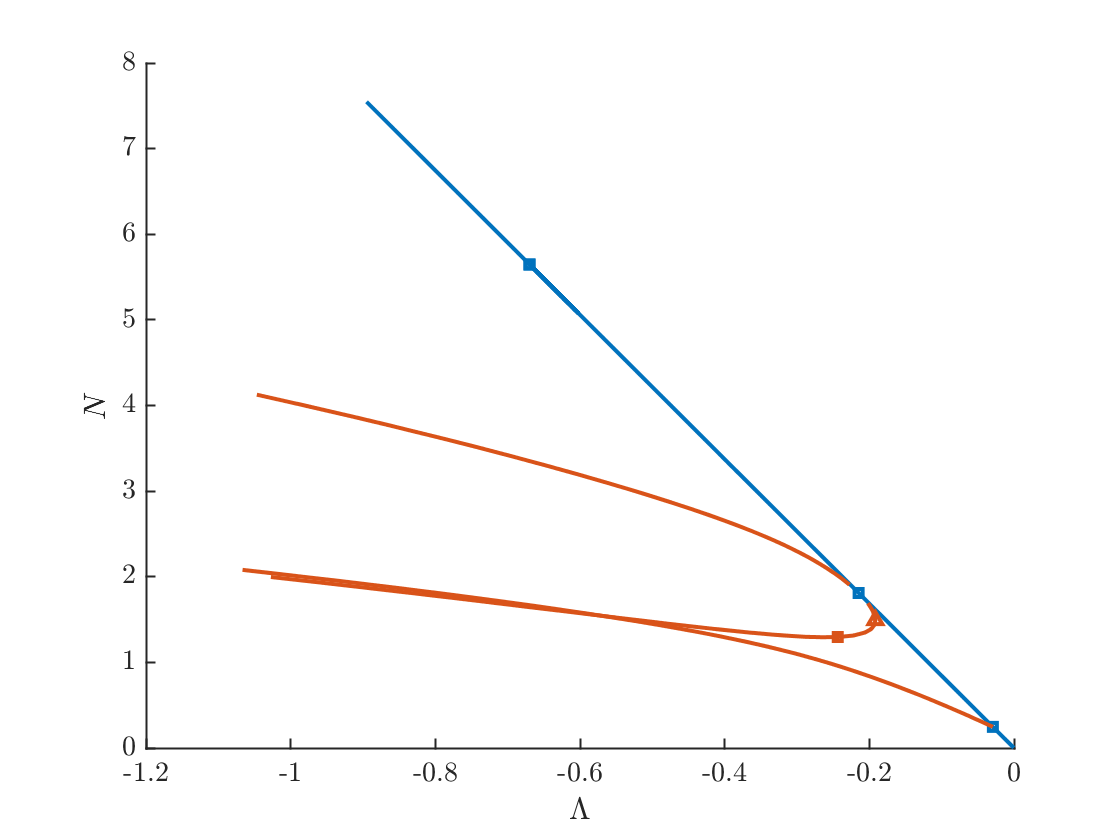

bifurcationDiagram('dumbbell',runNumber)

## Compute a branch that bifurcates from the third branch

Continues from the branch stored in `bn3` from the bifurcation point at `bl3(1)`

[bn5,bl5]=continueFromBranchPoint('dumbbell',runNumber,bn3,bl3(1),1,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/dumbbell/025/branch005.
No branching bifurcations found.


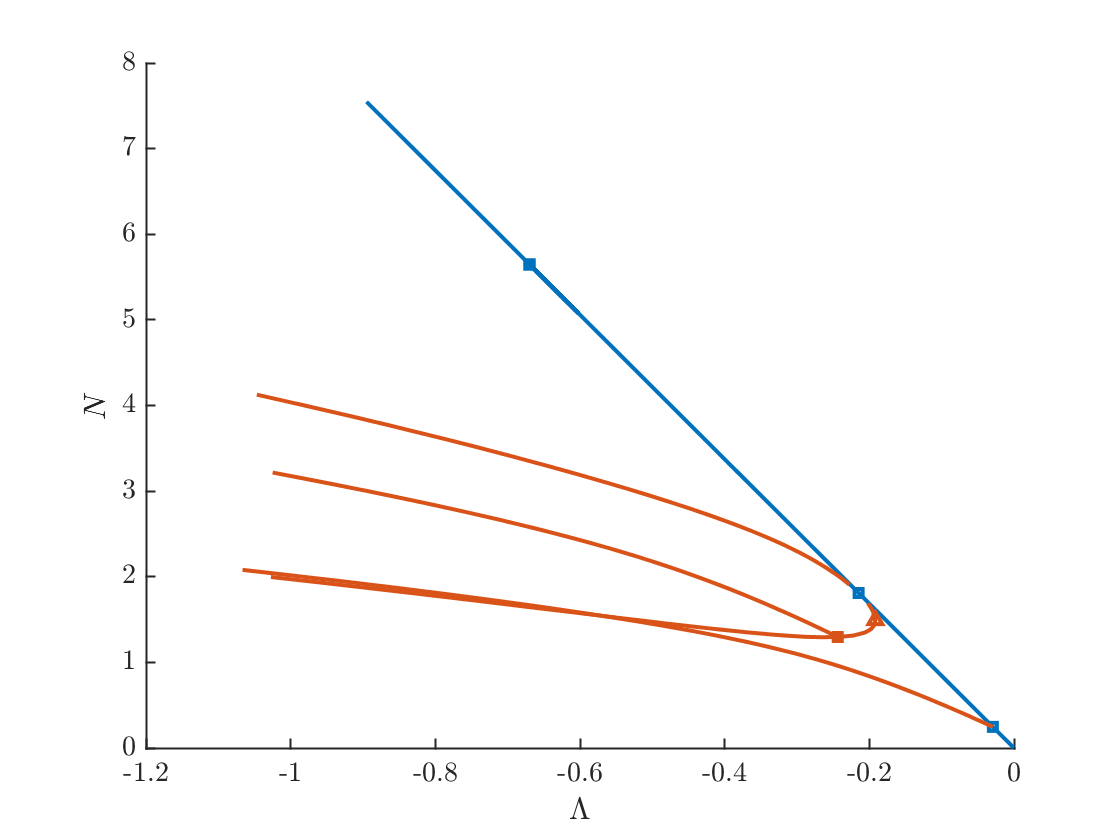

bifurcationDiagram('dumbbell',runNumber)

## Compute a large-amplitude solution, save it to a file, and compute its continuation

File saved to data/dumbbell/025/savedFunction.001.
File number is 1. 


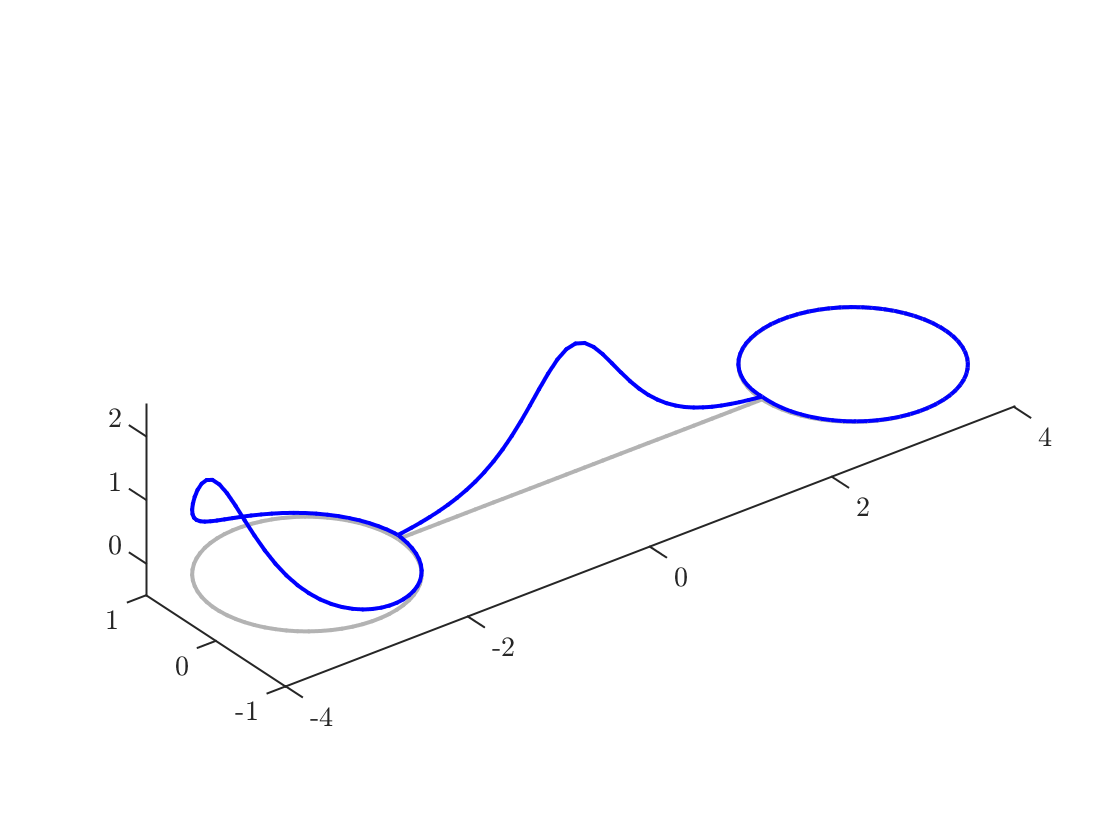

filenumber=saveDumbbellStandingWave(runNumber,-4,[1 2],[1 1]);

options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn6,bl6]=continueFromSaved('dumbbell',runNumber,filenumber,-1,options);

N threshold crossed.
Branch number 6.
Data saved to directory data/dumbbell/025/branch006.
No branching bifurcations found.


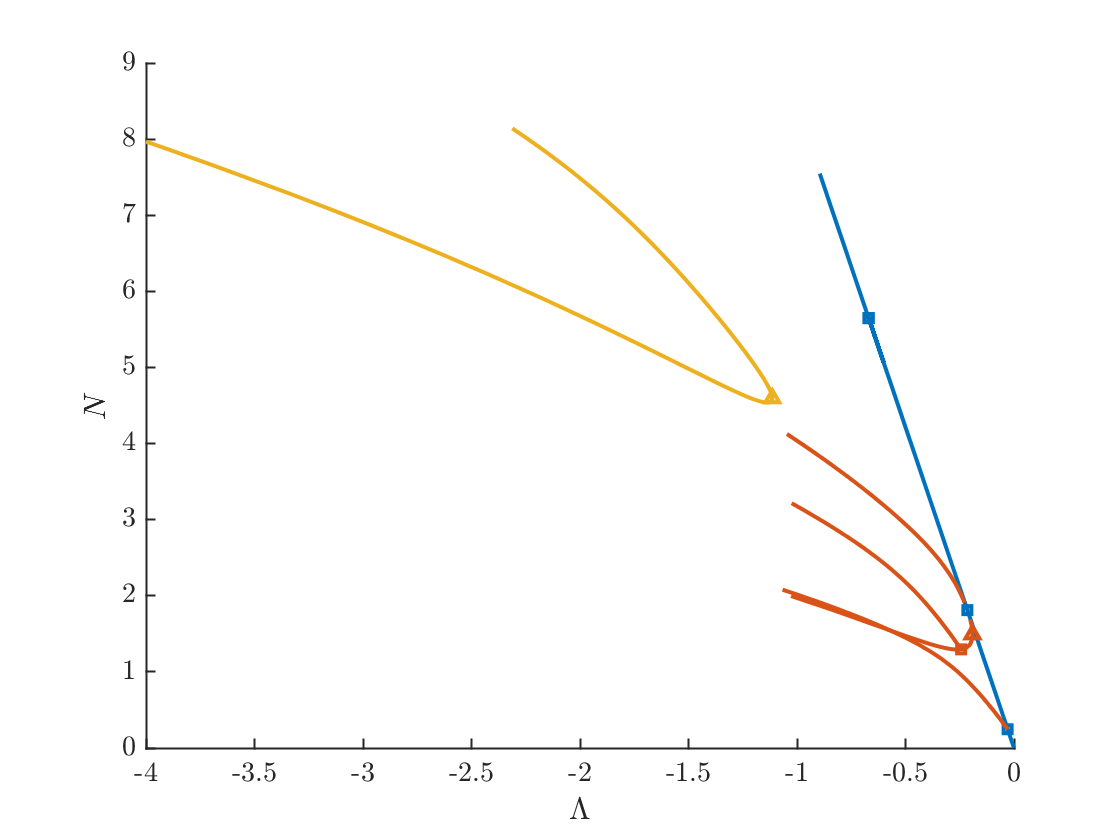

bifurcationDiagram('dumbbell',runNumber)

## Extend a previously-computed branch

Continuation of the branch stored in `bn1.`

[bn7,bl7]=continueFromEnd('dumbbell',runNumber,bn1,'last',2,2,options);

N threshold crossed.
Branch number 7.
Data saved to directory data/dumbbell/025/branch007.
Branching Bifurcation at solution number 4.


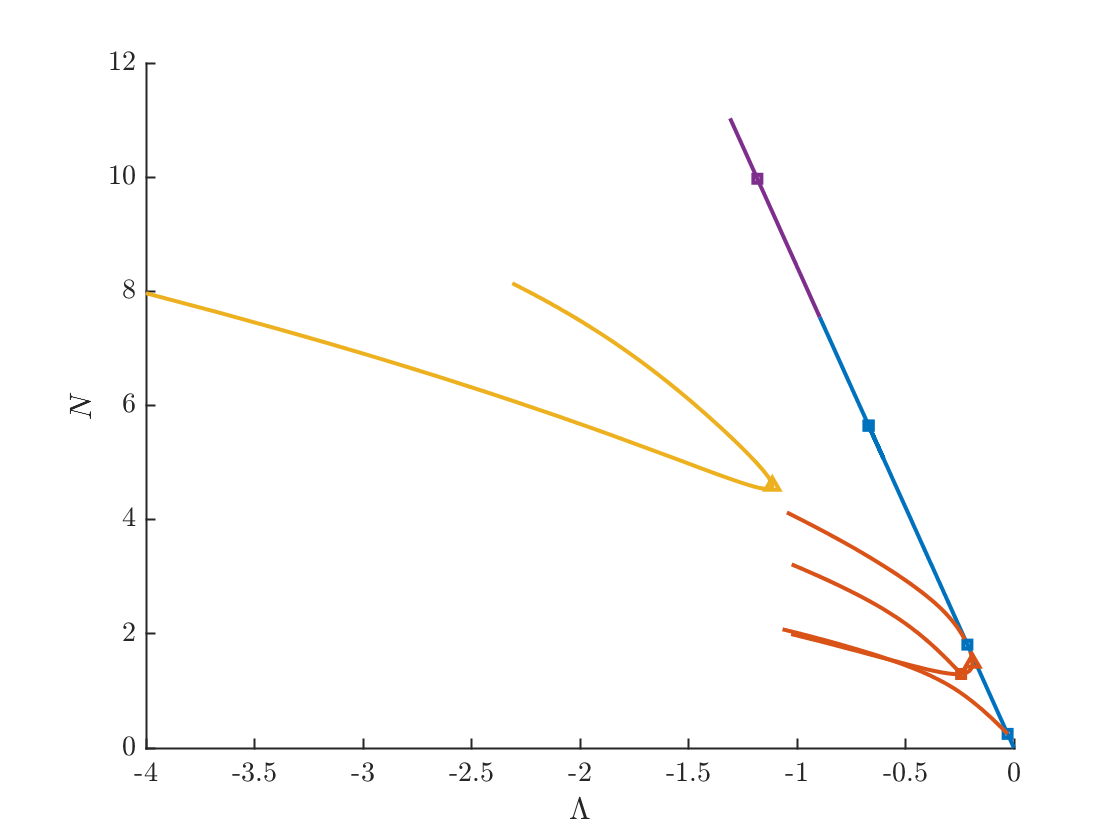

bifurcationDiagram('dumbbell',runNumber)